% 1. create the simulation name and the folder to save all simulated
% samples and parameters

% give this simulation a name
SimulationName='Simulation_NoiseSource_20240105';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_NoiseSource_20240105/'

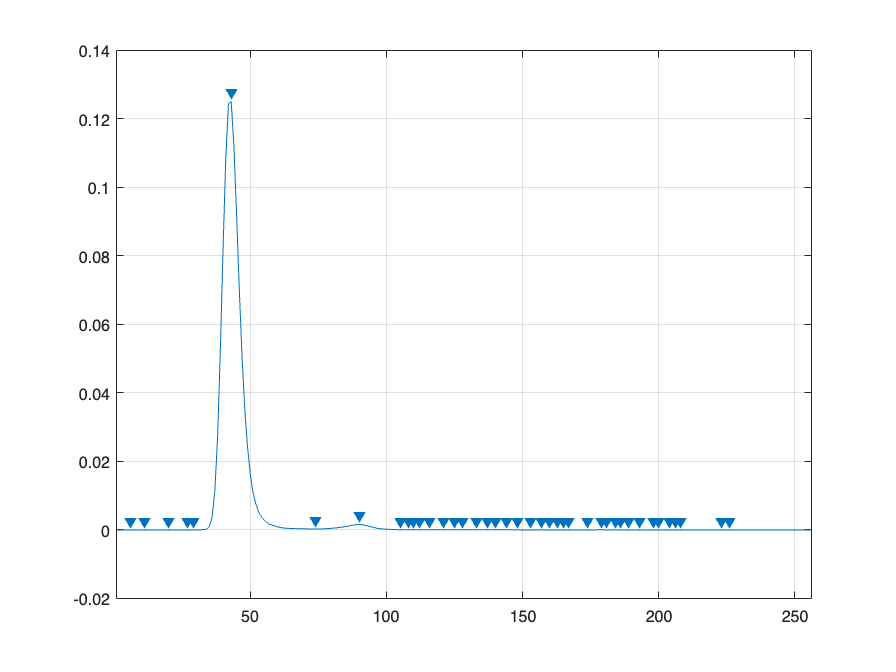

cd(filepath)

TP = 1000000;
p1 = 0.5;
p2 = 1 - p1;
tau1 = 2.14;
tau2 = 0.69;

PopulationName = 'TestNoiseSource_Population_20240105.mat';

% 2. load prf, calculate the full width half maximum of the prf; use the FWHM to
% generate a corresponding gaussian PRF for PMT simulation

PrfName_original = 'prf_InsightBottomGreen_20231017.mat';

load(PrfName_original)
figure
findpeaks(prf)

[pks, locs, width, p] = findpeaks(prf); % Derive the peak location and the FWHM of the PRF curve
width(6)*(12.5/256) % The main peak of the PRF is the 6th peak. This is the FWHM of experimental collected PRF

ans = 0.3423


gaussian_x = (-80:1:256)*(12.5/256); % Create x axis
gaussian_x = (1:1:256)*(12.5/256); % Create x axis
channel_num = length(gaussian_x);

PMT_width = width(6)*(12.5/256);
% PMT_width = (12.5/256)*width(6)/2;
% PMT_width = 340/1000
PMT_sigma = (PMT_width)/2.355 % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355
PMT_miu = locs(6) * (12.5/256) % Guassian distributio mean same as the peak location

[PRF_PMT, PRF_PMT_norm] = CreatePRF(gaussian_x, PMT_sigma, PMT_miu);

% 3. create a Gaussian PRF  hybrid detector (HBD) prf
HBD_width = 200/1000 % 120 ps accroding to BH website https://www.becker-hickl.com/products/hybrid-photo-detectors/
HBD_sigma = (HBD_width)/2.355 % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355
HBD_miu = locs(6) * (12.5/256) % Guassian distributio mean same as the peak location

[PRF_HBD, PRF_HBD_norm] = CreatePRF(gaussian_x, HBD_sigma, HBD_miu);

figure
plot(gaussian_x, PRF_PMT_norm)
hold on
plot(gaussian_x, PRF_HBD_norm)
legend('PMT', 'Hybrid detector')
hold off

load(PopulationName); 

n1_HBD = conv(counts, PRF_HBD);
n_HBD = n1_HBD(1:256) + n1_HBD(257:512);

n1_PMT = conv(counts, PRF_PMT);
n_PMT = n1_PMT(1:256) + n1_PMT(257:512);

fitting_range = [1 256];
Emp_anlytical_HBD = CalcEmpLft(fitting_range, n_HBD)
Emp_anlytical_PMT = CalcEmpLft(fitting_range, n_PMT)

Emp_anlytical_HBD > Emp_anlytical_PMT

channel_num = 256;

PRF_width_all = 100:10:400;
PRF_miu = 100 * (12.5/256);
PRF_miu = locs(6) * (12.5/256);
gaussian_x = (1:1:channel_num)*(12.5/channel_num);

xsim = (1:1:(2*channel_num))*(12.5/channel_num);
counts = 1000000*(p1*exp(-xsim/tau1)+p2*exp(-xsim/tau2));

fitting_range = [1 channel_num*3-1];

Emplft_anlytical = zeros(1, length(PRF_width_all));
n_all_photons = zeros(1, length(PRF_width_all));
n1_all_photons = zeros(1, length(PRF_width_all));

n_all_histogram = zeros(length(PRF_width_all), channel_num);
n1_all_histogram = zeros(length(PRF_width_all), channel_num*3-1);


figure

for i_width = 1:length(PRF_width_all)
    PRF_width = PRF_width_all(i_width)/1000;
    PRF_sigma = (PRF_width)/2.355; % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355
    [PRF, PRF_norm] = CreatePRF(gaussian_x, PRF_sigma, PRF_miu);

    n1 = conv(counts, PRF);
    n = n1(1:channel_num) + n1(channel_num+1:channel_num*2);

    n_all_histogram(i_width, :) = n;
    n1_all_histogram(i_width, :) = n1;

    n_all_photons(i_width) = sum(n);
    n1_all_photons(i_width) = sum(n1);


    Emplft_anlytical(i_width) = CalcEmpLft(channel_num, fitting_range, n1);

end


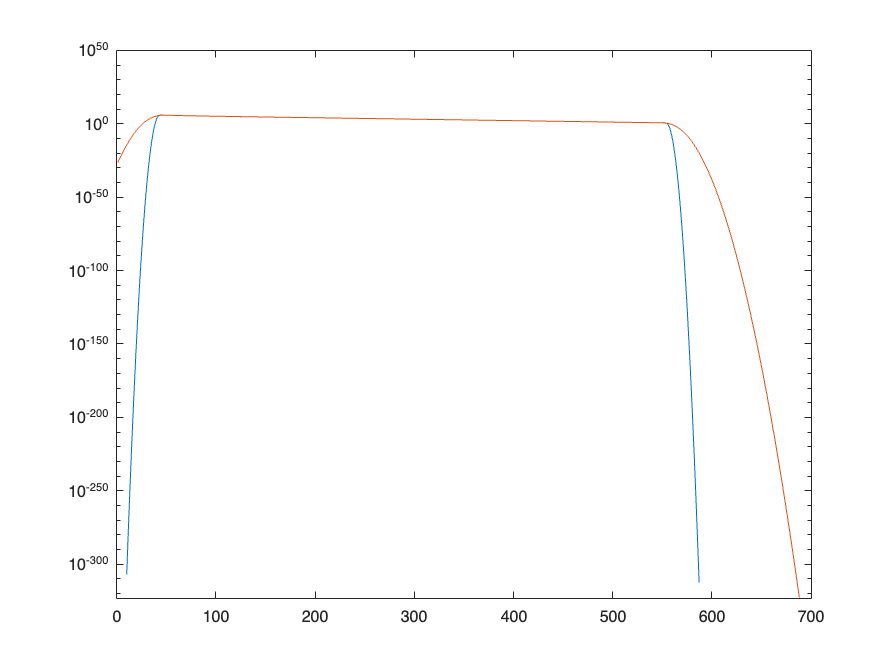

figure
semilogy(n1_all_histogram(1,:))
hold on
semilogy(n1_all_histogram(end,:))


figure
plot(PRF_width_all, Emplft_anlytical)

figure
plot(PRF_width_all, n_all_photons)

figure
plot(PRF_width_all, n1_all_photons)




function EmpLft = CalcEmpLft(channel_num, range, n)

x_axis = (1:1:(range(2)-range(1)+1))*(12.5/channel_num);
EmpLft = sum(n(range(1):range(2)).*x_axis)/sum(n(range(1):range(2)));

end



function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 10000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

    % Running the fitting
    spc_fitexp2prfGY(ch); 

    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;

end

function [PMT_y, PRF_PMT_norm] = CreatePRF(PMT_x, PMT_sigma, PMT_miu)

PMT_y = 1/(PMT_sigma*sqrt(2*pi))*exp(-(PMT_x-PMT_miu).^2/(2*PMT_sigma^2)); % Calculate y axis of the Gaussian distribution
PMT_y = PMT_y/sum(PMT_y); % Normalize the Gaussian distribution with sum being 1

PRF_PMT_norm = PMT_y/max(PMT_y);

end
